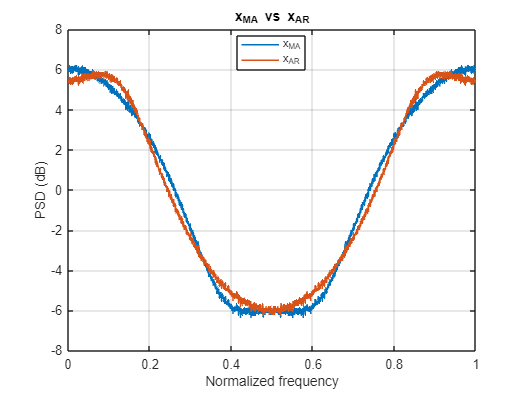

clear;
clc;
close all;
M = 2 ; % M = 2 , 5 , 10
N = 5000000;
v = randn(1, N);
b = [1, 0.75, 0.25];
a = 1;
x_MA = filter(b, a, v);

R = zeros(M, M); %covariance matrix
r = zeros(M,1); 

for i = 1:M
    for j = 1:M
        R(i,j) = rx(v, b, a, abs(i-j)) ; %in this problem we have r(1) = r(-1) so we can use abs()
    end
    r(i,1) = rx(v, b, a, i) ;
end

w = inv(R) * r ; %Yule-walker equations

var_v_AR = rx(v, b, a, 0 ) - (w.')*(r) ;
v_AR = sqrt(var_v_AR) * v ;  % white noise for AR

x_AR = filter(1, [1; -w].', v_AR);

%Plot x_MA and x_AR
figure('Color','w','Name','PSD: MA vs AR (Welch)');
[Pma, F] = pwelch(x_MA, 4096, 2048, 4096, 1, 'twosided');
[Par, ~] = pwelch(x_AR, 4096, 2048, 4096, 1, 'twosided');
plot(F, 10*log10(Pma), 'LineWidth', 1.2);
hold on;
plot(F, 10*log10(Par), 'LineWidth', 1.2);
grid on;
xlabel('Normalized frequency');
ylabel('PSD (dB)');
title('x_{MA} vs x_{AR}');
legend('x_{MA}', 'x_{AR}', 'Location', 'best');



function z = rx (v ,b ,a ,L)
    b_sec = [zeros(1,L) , b ] ;
    x = filter(b, a, v);
    y = conj(filter(b_sec, a, v));
    z = mean(x .* y) ;
end